# Pitch Parameter Estimation

This lab shows how to find the thrust, damping, and stiffness parameters of the pitch-only system (i.e., yaw axis is locked).

## Concept Review

The equation of motion of the Aero 2 when condifugred as a 1 DOF pitch-only system is


$$J_p\ddot{\theta} + D_p{\dot{\theta}} + K_{sp}\theta = \tau_p=K_{pp} D_t V_p(t)$$


where $\theta$ is the pitch angle, $J_p$ is the equivalent moment of inertia acting about the pitch axis, $D_p$ is the viscous damping, $K_{sp}$ is the stiffness, $K_{pp}$ is the force thrust gain, $D_t$ is the distance from the pivot point to the propeller, $V_p$ is the voltage applied to the front or pitch rotor motor. 

The corresponding open-loop transfer function is a second-order transfer function


$$P(s) = \frac{\Theta(s)}{V_p(s)} = \frac{ \frac{D_tK_{pp}}{J_p} } {s^2 + \frac{D_p}{J_p}s + \frac{K_{sp}}{J_p}}$$


In this lab we identify the pitch thrust gain, $K_{pp}$, damping, $D_p$, and stiffness, $K_{sp}$. 

## Lab Procedure

Apply a step voltage to the front rotor and then set it to 0V to see the free-oscillation response. Measure the damping, $D_p$, and stiffness, $K_{sp}$, from the free-oscillation response and the thrust, $K_{pp}$, from the step response.

### Setup

- Make sure the Aero 2 has been tested as instructed in the Quick Start Guide. 

- Launch MATLAB and browse to the working directory that includes the Simulink models for this lab.

- Configure the Aero 2 in the 2 DOF Helicopter configuration: 

- **Unlock** the pitch axis and **lock **the yaw axis.

- Rear rotor 1 is **vertical **and front rotor 0 is **horizontal**.

- Adjust masses on each rotor.

- Connect the USB cable to your PC/laptop.

- Connect the power and turn the power switch ON. The Aero base LED should be red.

### Lab 1: Get Open-Loop Response

The open-loop response can be obtained by running the `q_aero2_pitch_step `Simulink model shown Figure 1 with QUARC. 

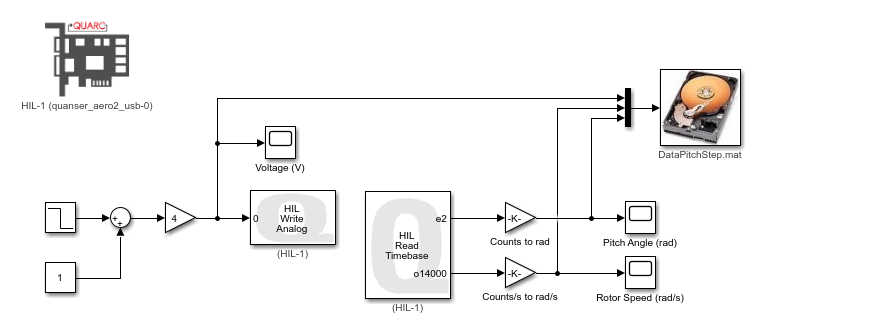

Figure 1 - Simulink model used with QUARC to apply a voltage to the front pitch rotor and measure the pitch angle.

The Simulink model uses the `HIL Write Analog `and `HIL Read Timebase `blocks from the *QUARC Targets *library to apply a voltage to the front rotor and measure the corresponding pitch angle response. The response is saved into a MATLAB *.mat files using the `To Host File `block. This can then be used to plot the results and perform the parameter estimation analysis. 

Build and run the following Simulink model in QUARC by clicking on the *Monitor & Tune* button.

%% Load Simulink model
open("q_aero2_pitch_step.slx");

The scopes shown in Figure 2 show the pitch angle response from applying a voltage to the front pitch rotor.

 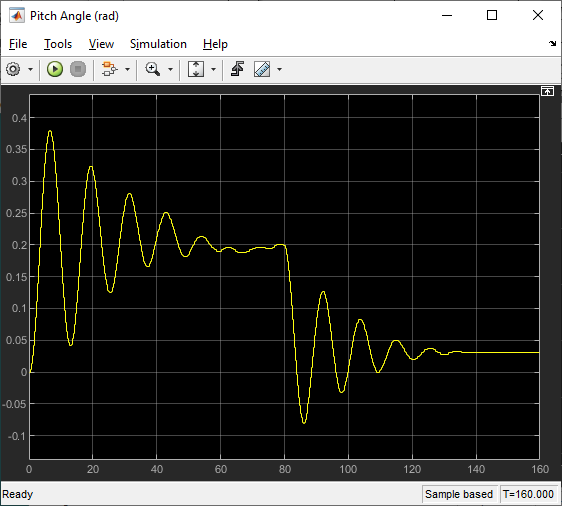

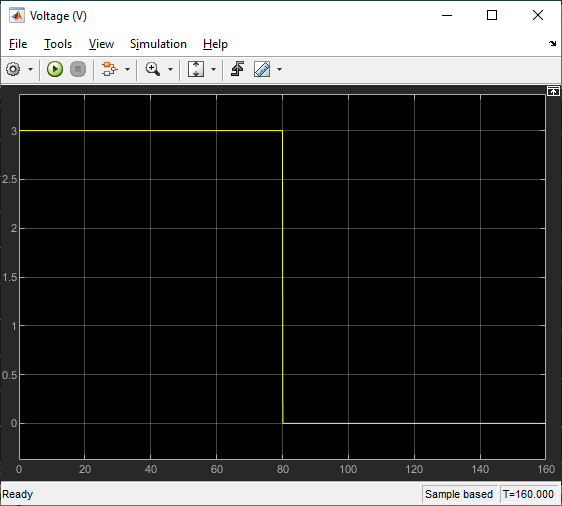

Figure 2 - Pitch angle response from applying a step to the front pitch rotor. 

Plot measured response

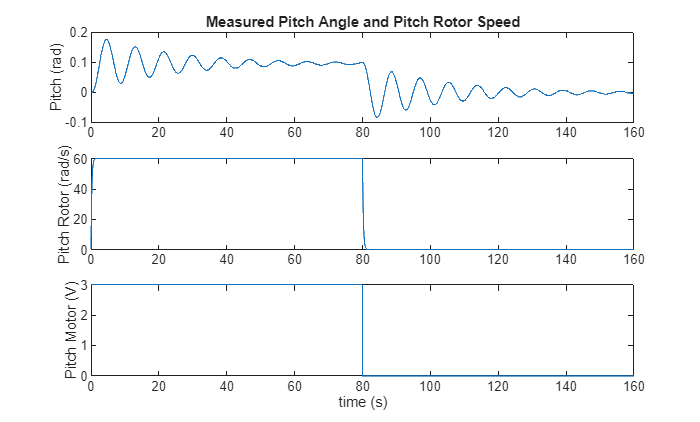

%% Load measured data from past run
load('DataPitchStep.mat');
% store in variables
t = DataPitchStep(1,:); % time (s)
Vp = DataPitchStep(2,:); % pitch voltage (V)
wm_p = DataPitchStep(3,:); % rotor speed (rad/s)
theta = DataPitchStep(4,:); % pitch angle (rad)
%
subplot(3,1,1);
plot(t,theta);
title('Measured Pitch Angle and Pitch Rotor Speed');
ylabel('Pitch (rad)');
subplot(3,1,2);
plot(t,wm_p);
ylabel('Pitch Rotor (rad/s)');
subplot(3,1,3);
plot(t,Vp);
ylabel('Pitch Motor (V)');
xlabel('time (s)');

### Lab 2: Parameter Estimation

#### Finding the Pitch Stiffness and Damping

The prototype second-order transfer function when there is a steady-state value of $K_{ss}$ can be represented by the following


$$\frac{Y(s)}{U(s)}=\frac{K_{ss} \omega_n^2 }{s^2 + 2\zeta\omega_n + \omega_n^2}$$


where $\omega_n$ is the natural frequency and $\zeta$ is the damping ratio. Based on the plant transfer function, we can find the stiffness and viscous damping parameters using the equations


$$K_{sp} = J_p\omega_n^2$$



$$D_p = 2J_p\zeta\omega_n$$


The parameters can be calculated by measuring the natural frequency and damping ratio of the free-oscillation response.

#### Finding the Natural Frequency

The period of the oscillations in a system response can be found using the equation


$$T_{osc} = \frac{t_{n} - t_1}{n-1}$$


where $t_n$ is the time of the $n^{th}$ oscillation, $t_1$ is the time of the first peak, and $n$nis the number of oscillations considered. From this, the damped natural frequency (in radians per second) is


$$\omega_d = \frac{2 \pi}{T_{osc}}$$


and the undamped natural frequency is

$\omega_n = \frac{\omega_d}{\sqrt{1-\zeta^2}}$.

#### Finding the Damping Ratio

The damping ratio of a second-order system can be found from its response. For a typical second-order underdamped system, the subsidence ratio (i.e., decrement ratio) is defined as 


$$\delta = \frac{1}{n} \ln \frac{O_1}{O_n}$$


where $O_1$ is the peak of the first oscillation and $O_n$ is the peak of the $n^{th}$ oscillation. Note that $O_1 > O_n$, as this is a decaying response.

The damping ratio is defined


$$\zeta = \frac{1}{\sqrt{1+\left(\frac{2 \pi}{\delta}\right)^2}}$$


For more information, please see the Wikipedia [reference](https://en.wikipedia.org/wiki/Logarithmic_decrement#:~:text=The%20logarithmic%20decrement%20is%20defined,number%20of%20successive%2C%20positive%20peaks.).

Load the AERO 2 Parameters

%%
aero2_parameters;

Enter the peak value and time of the first (largest) overshoot and the last overshoot (n^th) of the *free-oscillation response*.

%% Measure first overshoot
O1 = 0.0676; % 0.1745, 0.127, 0.218;
t1 = 88.2460; % 4.286, 92.2,71.25;
% Measure nth overshoot
n = 4; % 8;
On = 0.0218; % 0.1222, 3.71e-2, 0.0131;
tn = 113.2680; % 29.4140, 125.7, 142.6;

Calculate the natural frequency and damping ratio of the free-oscillation response.

% Oscillation period (s)
Tosc = (tn-t1) / (n-1);
% Logarithmic decrement (i.e., subsidence ratio)
sigma = 1/n*log(O1/On);
% 
% Damping ratio
zeta = 1 / sqrt(1 + (2*pi/sigma)^2);
% Damped natural frequency (rad/s)
wd = 2*pi/Tosc;
% Undamped natural frequency (rad/s)
wn = wd / sqrt(1-zeta^2);

Calculate siffness and damping based on measured response.

% Stiffness (N.m/rad)
Ksp = Jp*wn^2

Ksp = 0.0132

% Damping (N.m/(rad/s))
Dp = 2*zeta*wn*Jp 

Dp = 0.0016

Based on the given moment of inertia, the stiffness and damping of the 1 DOF pitch system are: $K_{sp} = 0.00884$ N-m/rad and $D_p =0.00160$N-m/(rad/s).

### Finding the Thrust

Applying a step input voltage to the pitch rotor speed with an amplitude of $V_{p0}$, the open-loop transfer function model becomes:


$$\Theta(s)= \frac{ \frac{D_tK_{pp}}{J_p} } {s^2 + \frac{D_p}{J_p}s + \frac{K_{sp}}{J_p}
}\frac{V_{p0}}{s}$$


Applying the Final-Value Theorem (FVT) on the pitch transfer function, the steady-state angle


$$\theta_{ss} = \lim_{s \to 0} \frac{ \frac{D_tK_{pp}}{J_p} } {s^2 + \frac{D_p}{J_p}s + \frac{K_{sp}}{J_p}} V_{p0}= \frac{D_tK_{pp}}{K_{sp}} V_{p0}$$


Solving for the thrust


$$K_{pp} = \frac{\theta_{ss}K_{sp}}{D_t V_{p0}}$$


Find pitch thrust from step response

% Steady-state pitch angle at end of step input 120 sec (rad)
theta_ss_pp = 0.200; % 0.293;
% Rotor voltage at same time (V)
Vm_ss_pp = max(Vp);
% Pitch thrust gain (V)
Kpp = theta_ss_pp * Ksp / (Dt * Vm_ss_pp)

Kpp = 0.0053

Based on this experiment, the rotor thrust constant is $K_{pp} = 0.00387$ N/V.

### Lab 3: Model Validation

The model can be validated by running the hardware in parallel with the identified model using the `q_aero2_pitch_model_val.slx` Simulink model in QUARC. 

To do this: 

- Make sure with the identified parameters `Kpp`, `Dp`, and `Ksp` are loaded.

- Build and run the following Simulink model in QUARC by clicking on the *Monitor & Tune* button.

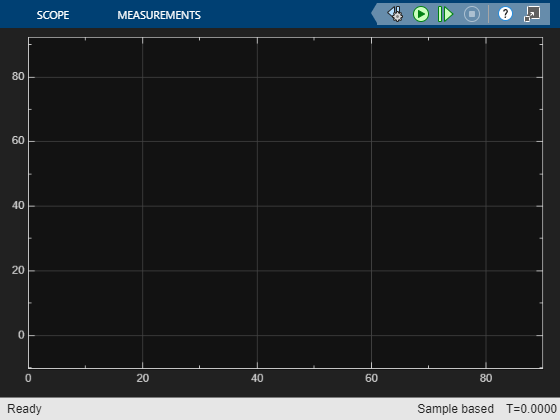

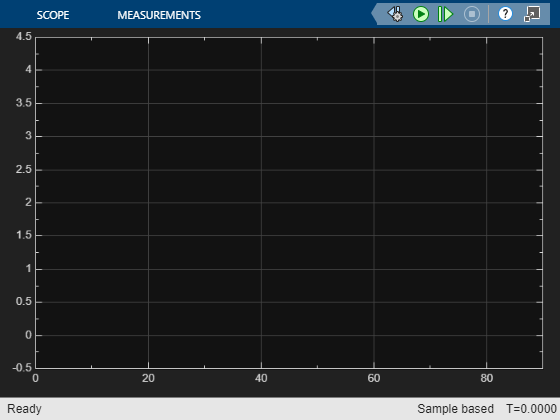

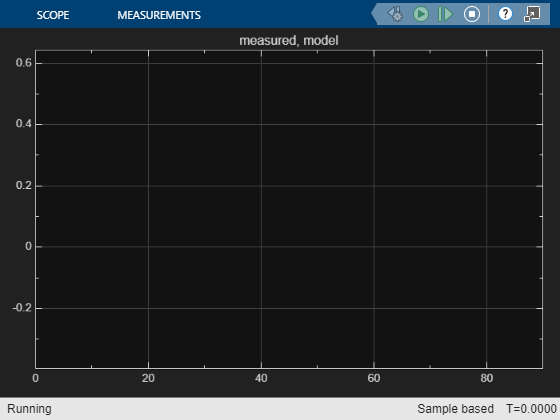

%% validate new model
open("q_aero2_pitch_model_val.slx")

Plot results. 

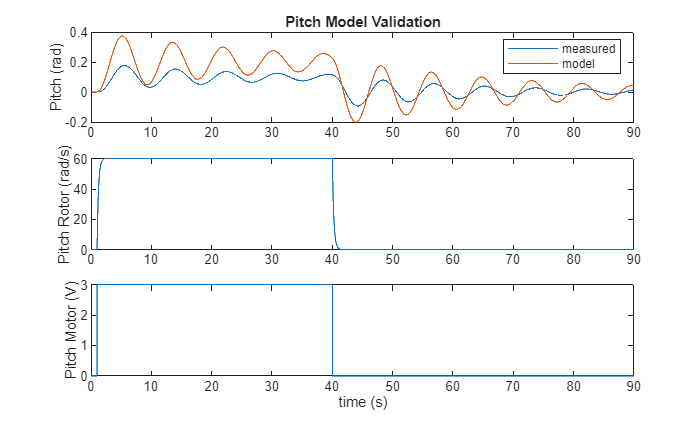

%% load saved data from MAT files
load("DataPitchModelVal.mat");
%
t = DataPitchModelVal(1,:); % time (s)
Vp = DataPitchModelVal(2,:); % pitch rotor voltage (V)
wm = DataPitchModelVal(3,:); % pitch rotor speed (rad/s)
theta_meas = DataPitchModelVal(4,:); % measured pitch angle from hardware (rad)
theta_sim = DataPitchModelVal(5,:);  % simulated pitch angle from model (rad)
%
subplot(3,1,1);
plot(t,theta_meas,t,theta_sim);
title('Pitch Model Validation');
ylabel('Pitch (rad)');
legend('measured','model')
subplot(3,1,2);
plot(t,wm);
ylabel('Pitch Rotor (rad/s)');
subplot(3,1,3);
plot(t,Vp);
ylabel('Pitch Motor (V)');
xlabel('time (s)');

The model does not quite match the response measured from the Aero 2 hardware. As mentioned in *Aero2_2DOF_Modeling*, the model used to represent the motion of the Aero 2 pitch is an approximation. The actual system is higher-order and includes other aerodynamics that are not included. More accurate values could be obtained by using system identification software or other techniques, e.g., least-squares method. 